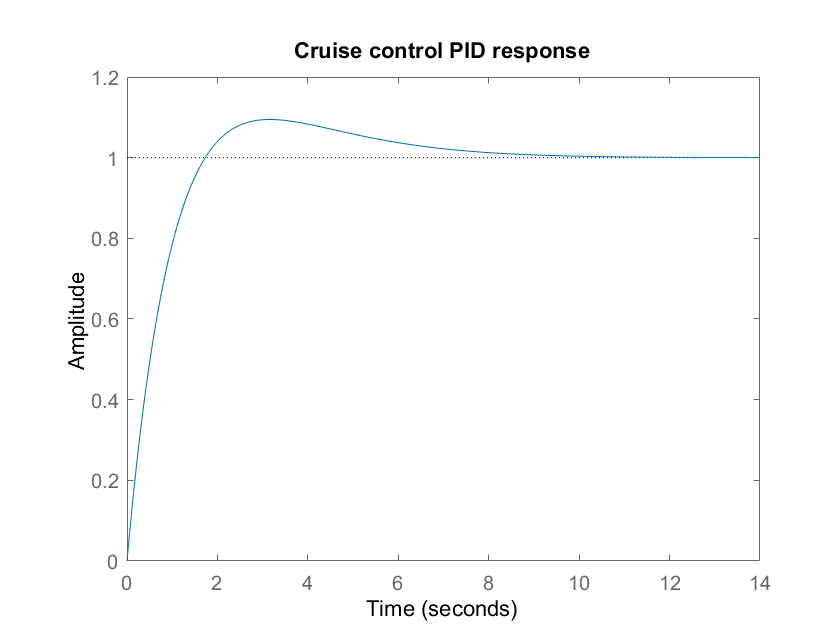

%% Problem 1 %%
close all;
%open('cruise_control_linear_PI.slx');
P1 = 10;            
I1 = 4;
s = tf('s');
PI_1 = tf(P1 + I1/s);              
cruise_plant_linear = 1/(8*s+1);
Ts_cruise = feedback(PI_1*cruise_plant_linear, 1);
figure;
step(Ts_cruise);
title("Cruise control PID response");

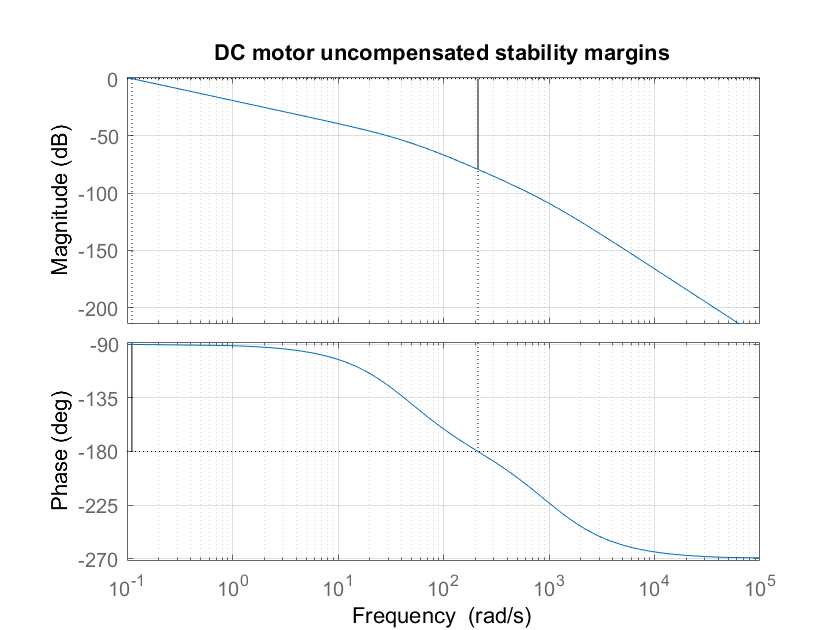

%% Problem 2 %%
close all;
syms Ra La Kt Kv Bm;
Ra = 1;
La = .001;
Kt = 5;
Kv = 5;
Bm = 20;
J = 1;
A = [-Ra/La -Kv/La 0; Kt/J -Bm/J 0; 0 1 0];
B = [1/La; 0; 0];
C = [0 0 1];
[num, den] = ss2tf(A, B, C, 0);
Gs_2 = tf(num, den);
figure;
margin(Gs_2),grid;
title("DC motor uncompensated stability margins");

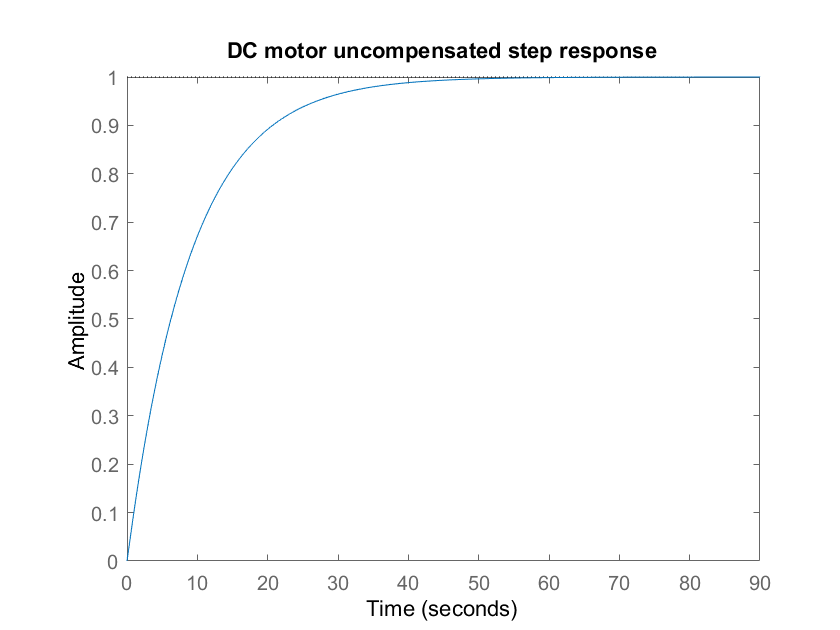

figure;
step(feedback(Gs_2,1));
title("DC motor uncompensated step response");

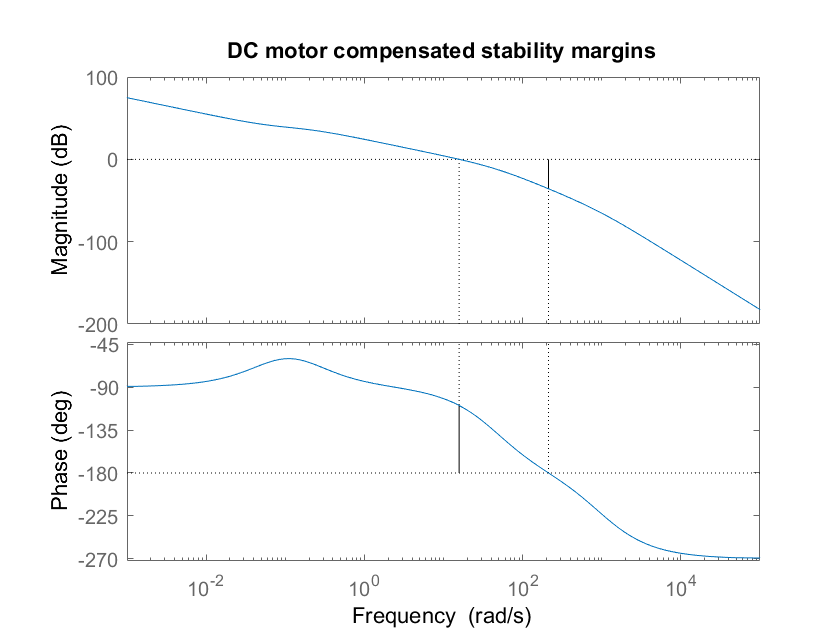

lead_phase = 30;
K_2 = 50;                               % SOME TRIAL AND ERROR
Beta_2 = 3;
w1_2 = .111/sqrt(Beta_2);
Hs_2 = (1+s/w1_2)/(1+s/(Beta_2*w1_2));
figure;
margin(K_2*Hs_2*Gs_2);
title("DC motor compensated stability margins");

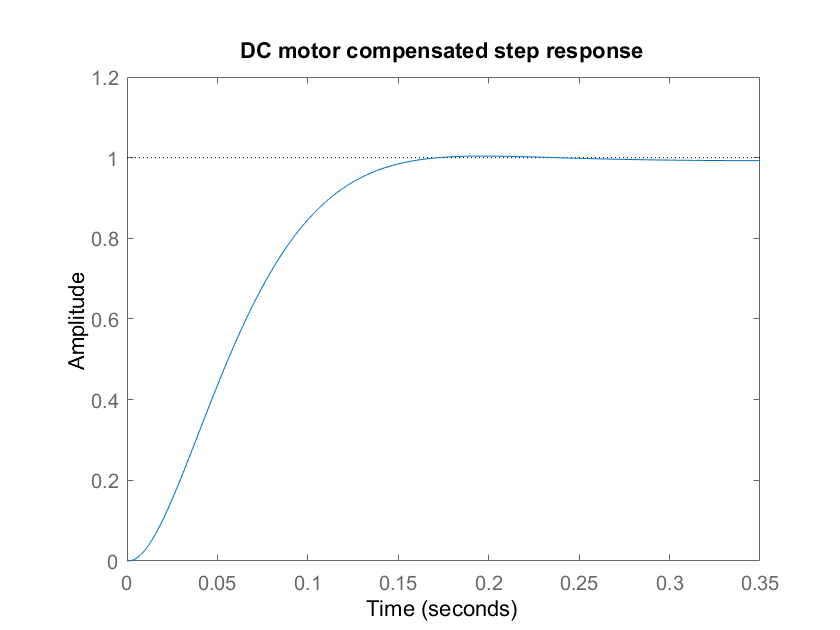

figure;
step(feedback(Hs_2*K_2*Gs_2, 1));
title("DC motor compensated step response");

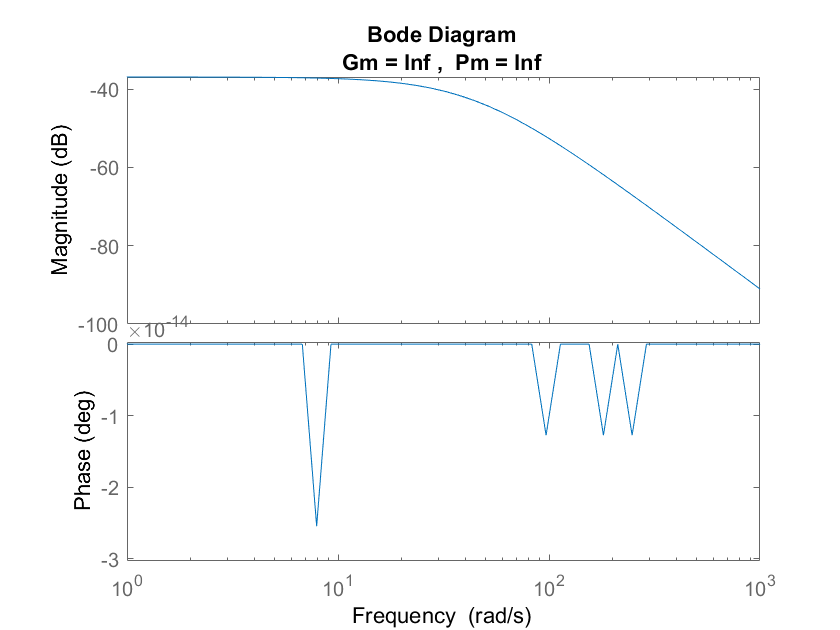

%% Problem 3 - maglev %%
close all;
s = tf('s');
maglev_plant = -28.1/(s^2 - 1962); % LINEARIZED W/O MOTOR DYNAMICS SLIDE 28
figure;
margin(maglev_plant);

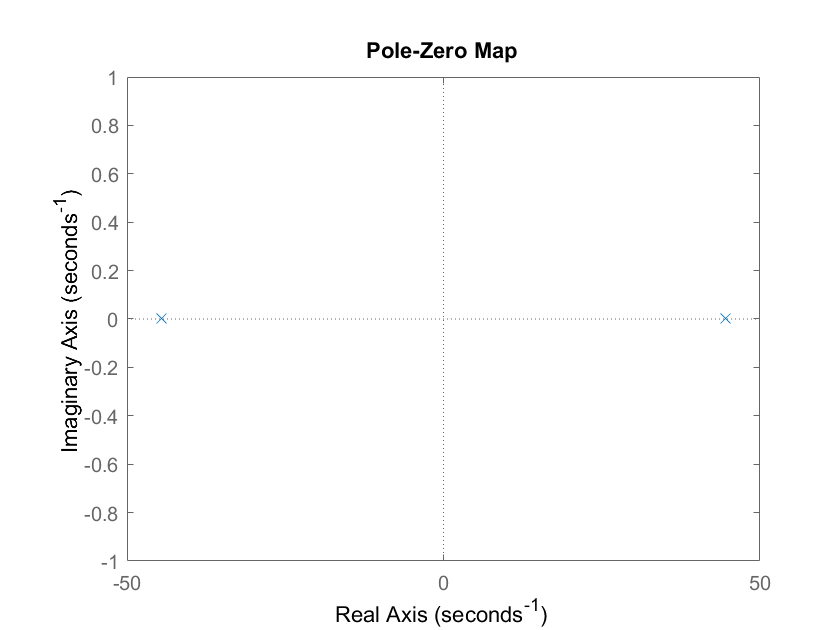

figure;
pzmap(feedback(maglev_plant, 1));

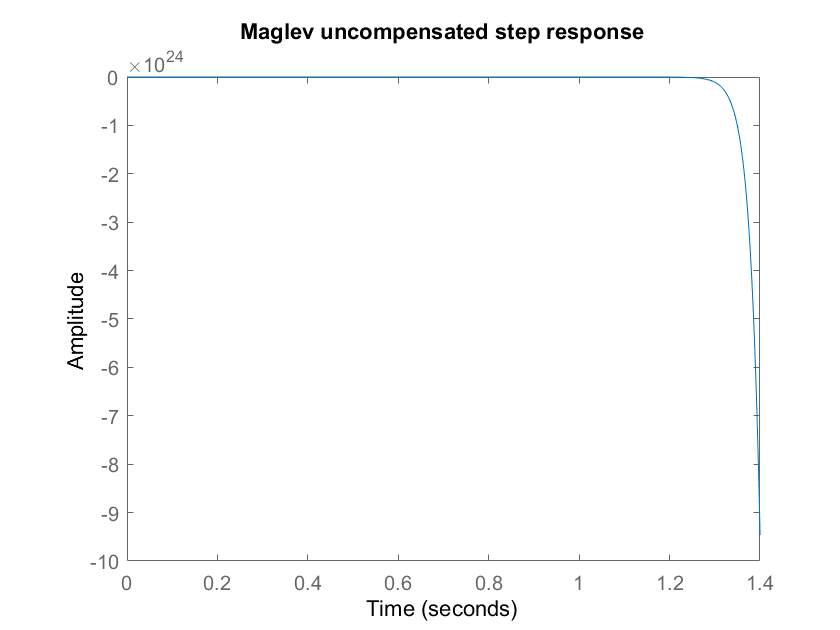

%title("Maglev uncompensated stability margins");
figure;
step(feedback(maglev_plant, 1));
title("Maglev uncompensated step response");

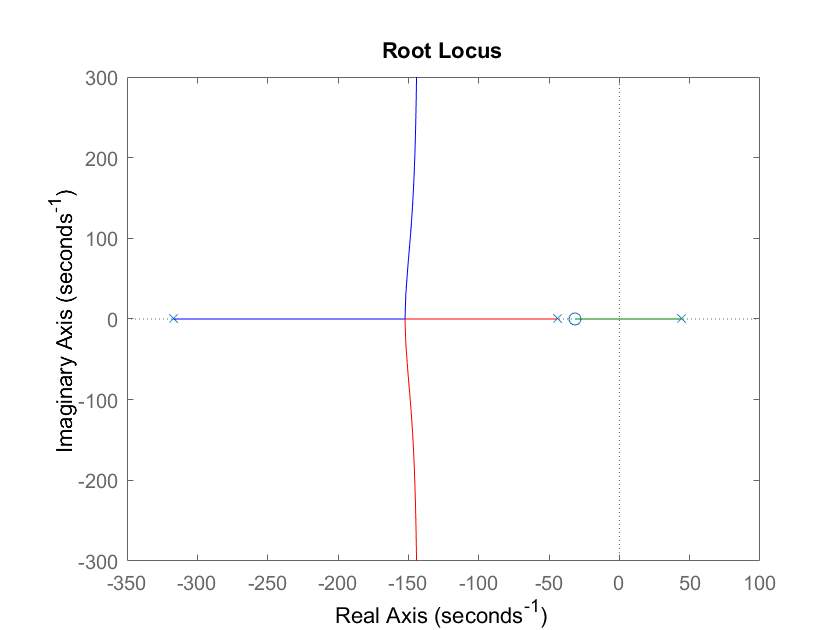

w_c_3 = 100;                               
phi_max_3a = 55;
beta_3a = (1+sind(phi_max_3a))/(1-sind(phi_max_3a));
w_3a = w_c_3/sqrt(beta_3a);                
maglev_comp = (1+s/w_3a)/(1+s/(w_3a*beta_3a));
maglev_forward_neg = -1* maglev_plant * maglev_comp;
rlocus(maglev_forward_neg);

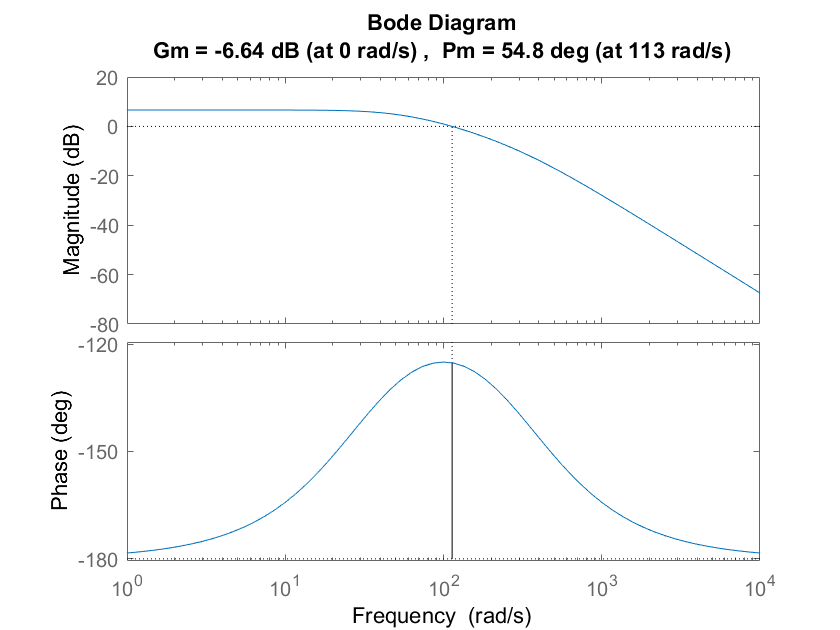

maglev_K = -150;                                   % W/O INTEGRATOR
maglev_LG = maglev_plant * maglev_comp * maglev_K; % W/O INTEGRATOR
figure;
margin(maglev_LG);

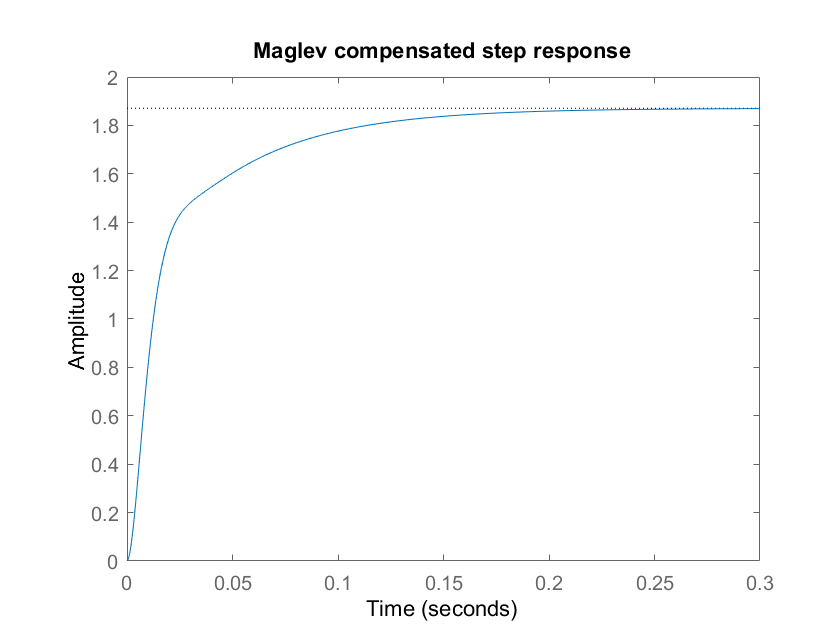

%title("Maglev compensated stability margins");
figure;
step(feedback(maglev_LG, 1));
title("Maglev compensated step response");

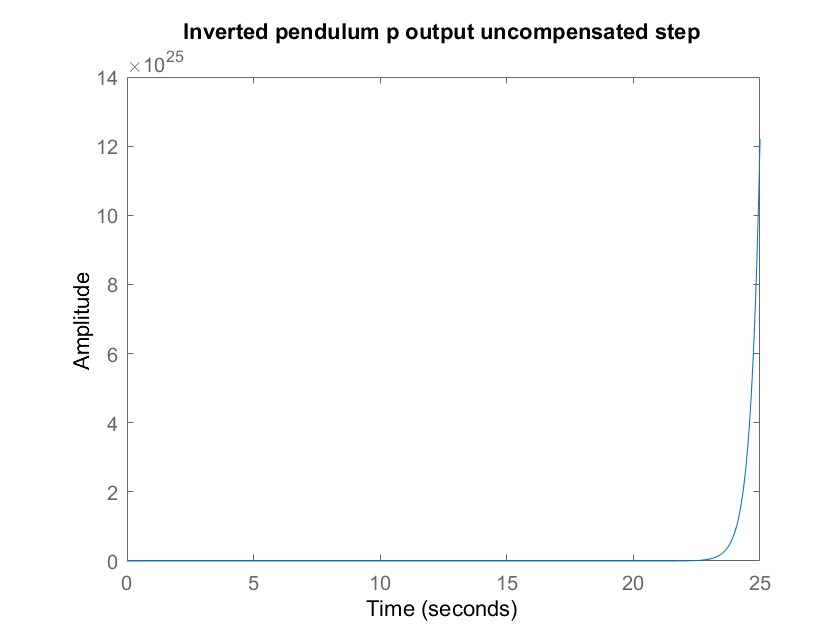

%% Problem 3 - inverted pendulum %% 
close all;
A_ip = [0 0 1 0; 0 0 0 1; 0 11.5 -1.84e-3 -8.08e-5; 0 7.2 -8.16e-4 -9.18e-5];
B_ip = [0 0 .0184 .00816]';
C_ip = [1 0 0 0; 0 1 0 0];
C_ip_p = C_ip(1,:);
C_ip_theta = C_ip(2,:);
D_ip = [0];
sys_ip_p = ss(A_ip, B_ip, C_ip_p, D_ip);
sys_ip_theta = ss(A_ip,B_ip, C_ip_theta, D_ip);
Gs_ip_p = tf(sys_ip_p);
figure;
step(Gs_ip_p);
title("Inverted pendulum p output uncompensated step");

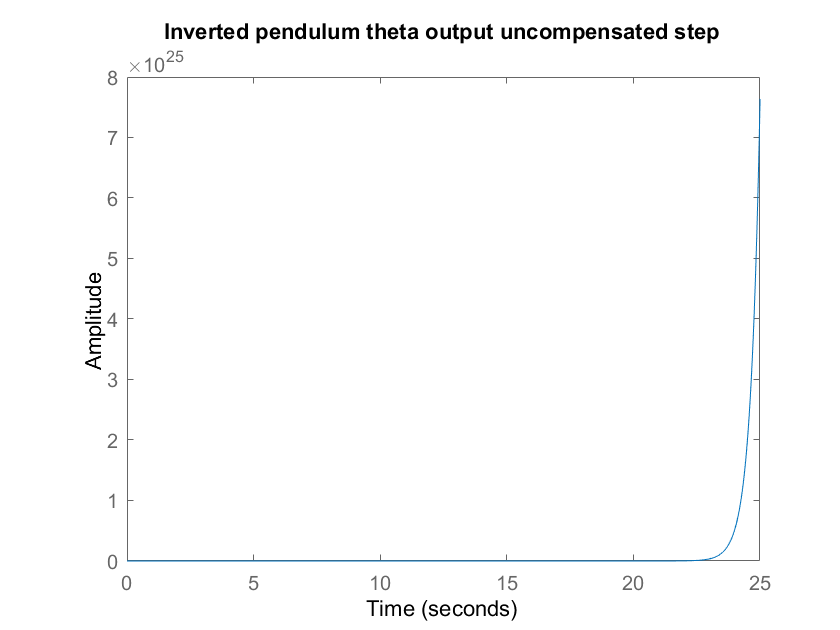

Gs_ip_theta = tf(sys_ip_theta);
figure;
step(Gs_ip_theta);
title("Inverted pendulum theta output uncompensated step");

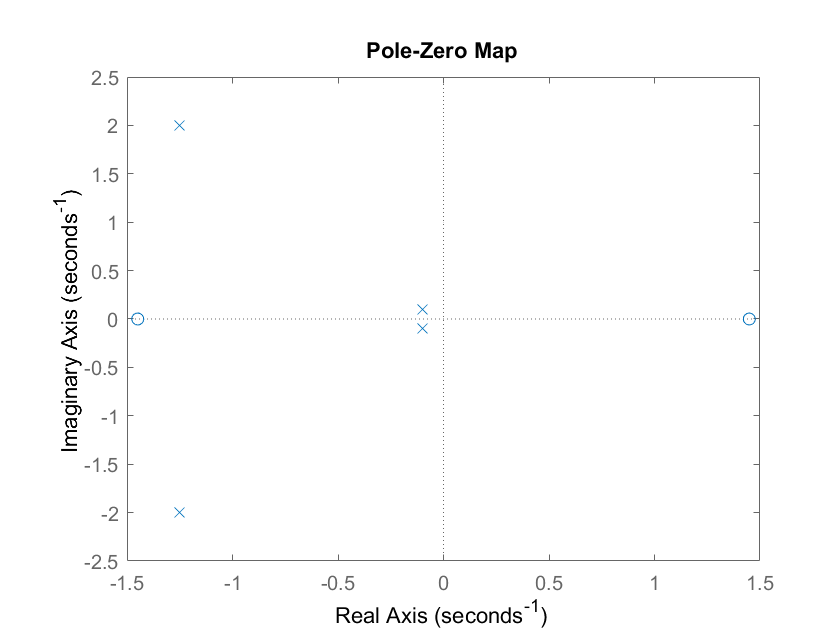

K_ip = place(A_ip, B_ip, [-.1+.1i, -.1-.1i, -1.25+2i, -1.25-2i]'); % SVFB
%K_ip = [-15.6 1730 -50.1 443];  % SVFB
%Kr_ip = -15.5;
%K_ip = [-625.1 4361.7 -691.9 2207.5];
Kr_ip = -2.86;
A_ip_comp = A_ip - B_ip*K_ip;
B_ip_comp = B_ip*Kr_ip;
sys_ip_p_comp = ss(A_ip_comp, B_ip_comp, C_ip_p, D_ip);
Ts_ip_p = tf(sys_ip_p_comp);
pzmap(Ts_ip_p);

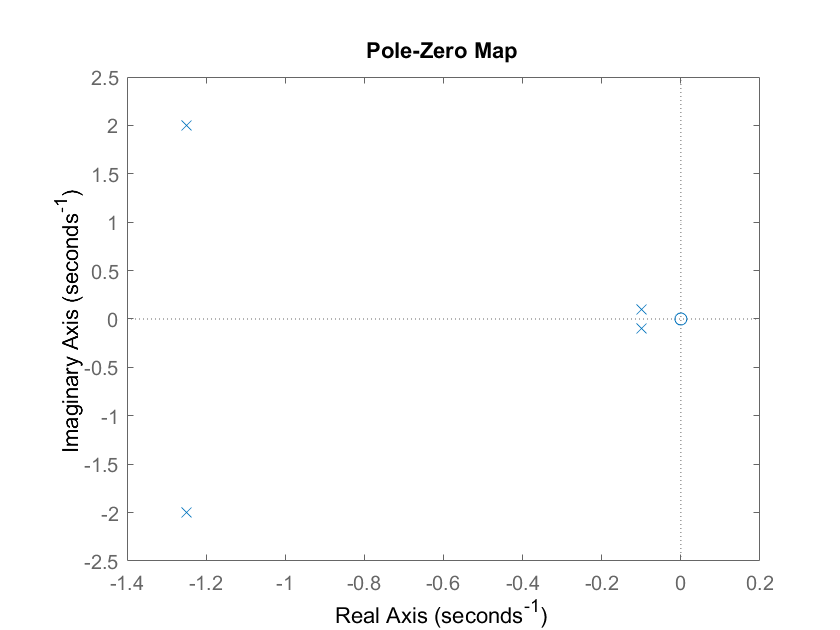

sys_ip_theta_comp = ss(A_ip_comp, B_ip_comp, C_ip_theta, D_ip);
Ts_ip_theta = tf(sys_ip_theta_comp);
pzmap(Ts_ip_theta);

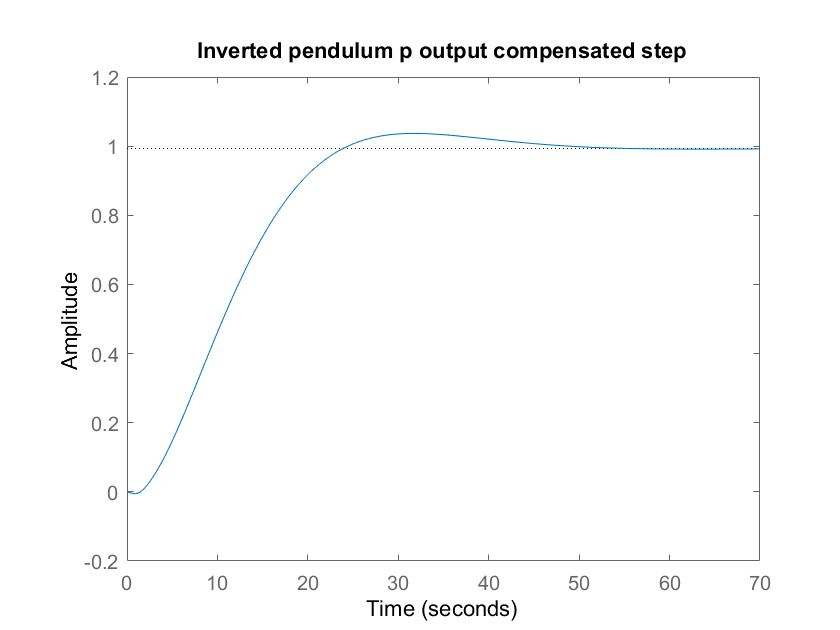

figure;
step(Ts_ip_p);
title("Inverted pendulum p output compensated step");

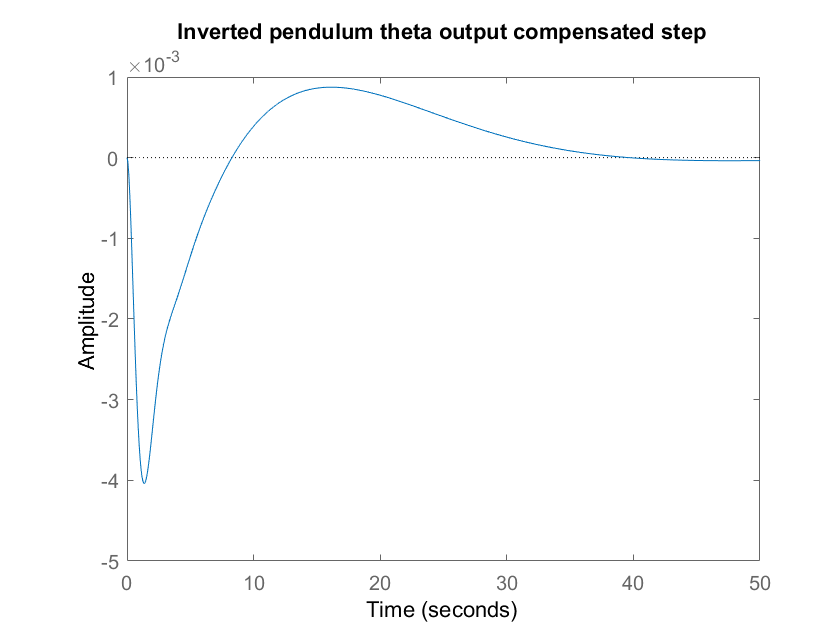

figure;
step(Ts_ip_theta);
title("Inverted pendulum theta output compensated step")

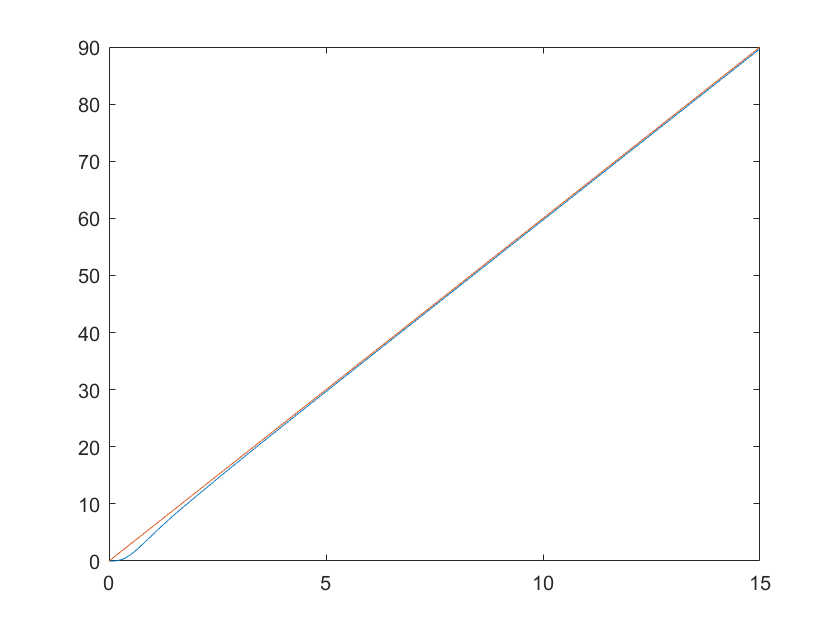

%% Problem 4 %%
close all;
s = tf('s');
t = 0:.01:15;
v = 6*t;
Gs_4 = 1/(1+.08*s)^2;
Ts_4_uncomp = feedback(Gs_4, 1);
resp_4_uncomp = lsim(Ts_4_uncomp, v, t);
K_4 = 20;                                       %% BASED ON STEADY-STATE ERROR REQS
alpha_4 = 6.32;                                 %% BASED ON MAGNITUDE AT Wc
wc_4 = 7;                                       %% WHERE PHASE MARGIN OF 30 DEGREES WOULD BE
w1_4 = wc_4/(10*alpha_4);
Hs_4 = (1/s)*(1+s/(alpha_4*w1_4))/(1+s/w1_4);
LG_4 = K_4*Hs_4*Gs_4;
Ts_4_comp = feedback(LG_4, 1);
resp_4_comp = lsim(Ts_4_comp, v, t);
figure;
plot(t, resp_4_comp);
hold on;
plot(t, v);
hold off;

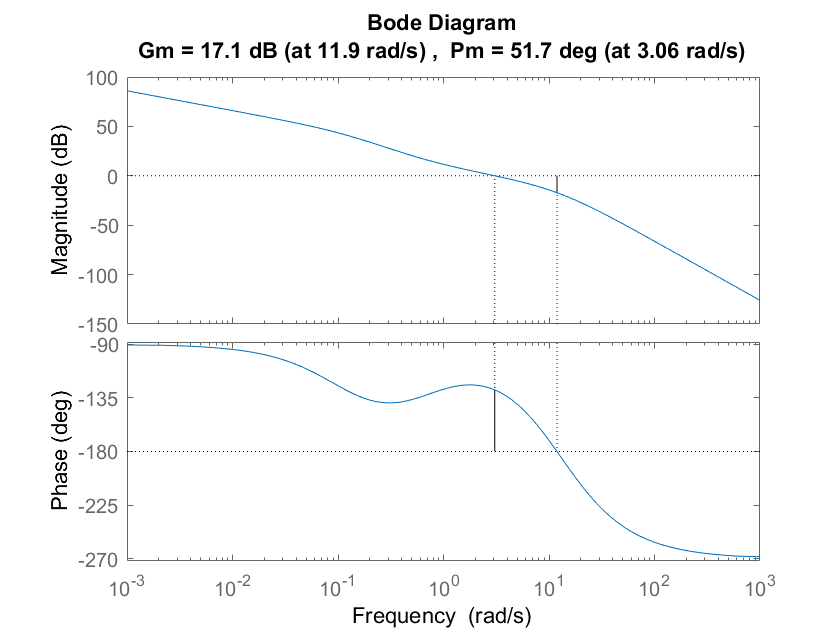

figure;
margin(LG_4);

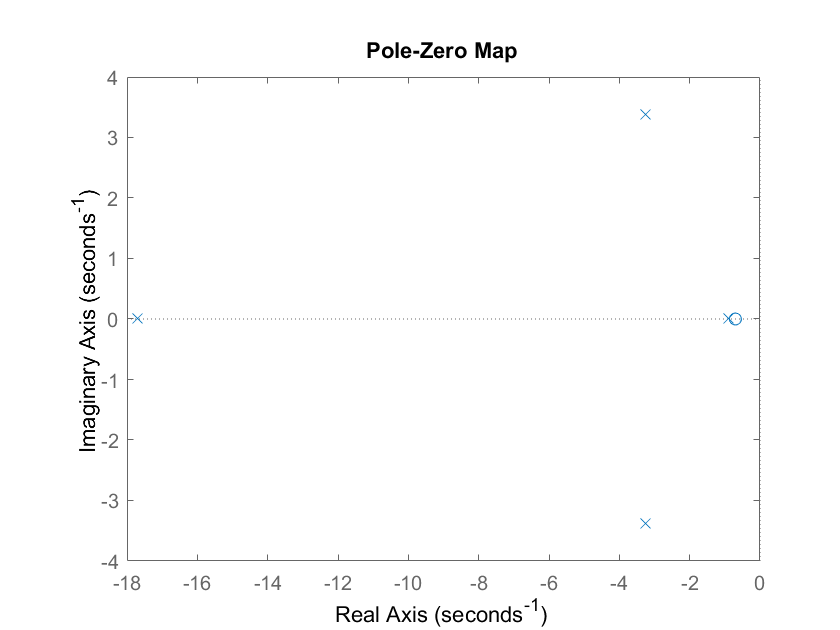

%b
figure;
pzmap(Ts_4_comp);

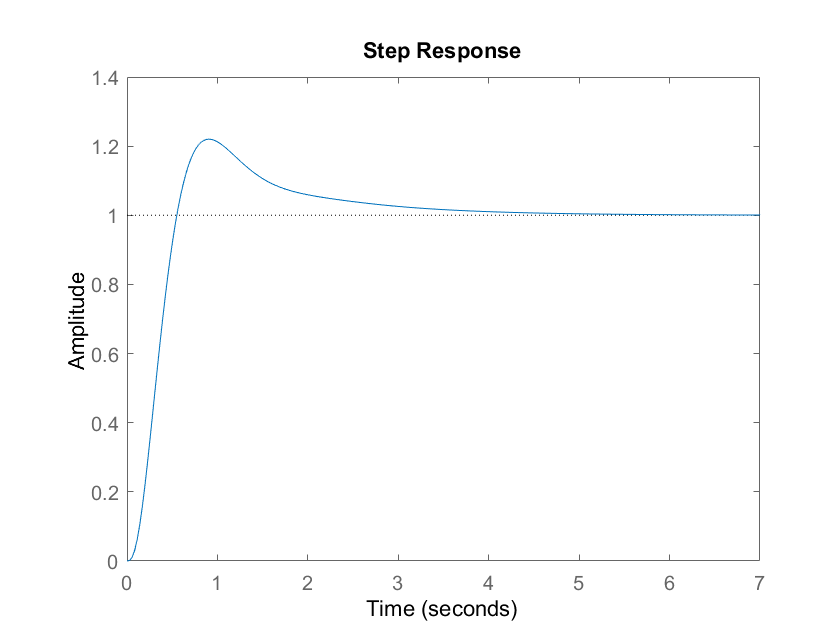

figure;
step(Ts_4_comp);

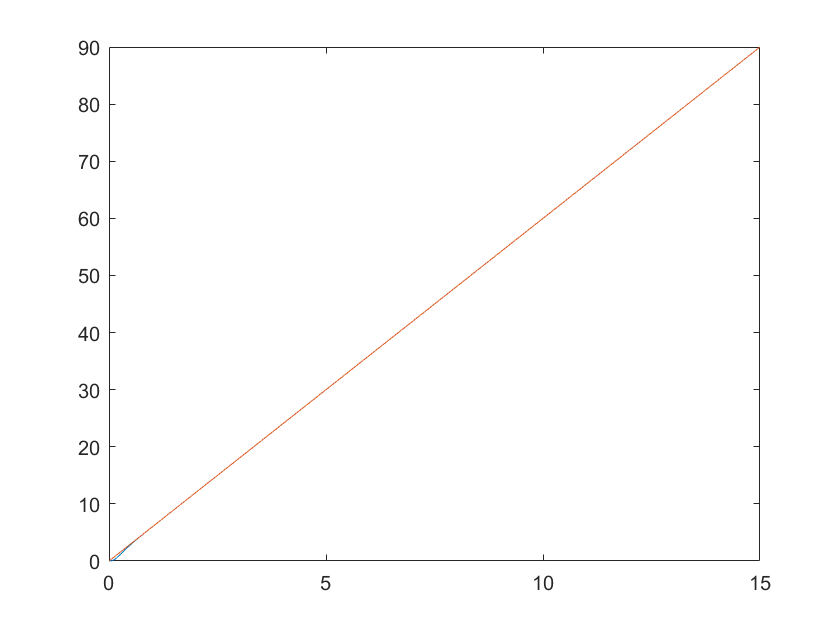

%c
lambda_4c = 0.1;
beta_4c = 3*lambda_4c;
Hs_4c = (1+beta_4c*s)*(1+.08*s)^2/((1+lambda_4c*s)^3 - (1+beta_4c*s));
LG_4c = Hs_4c*Gs_4;
Ts_4c = feedback(LG_4c, 1);
resp_4c = lsim(Ts_4c, v, t);
figure;
plot(t, resp_4c);
hold on;
plot(t, v);
hold off;

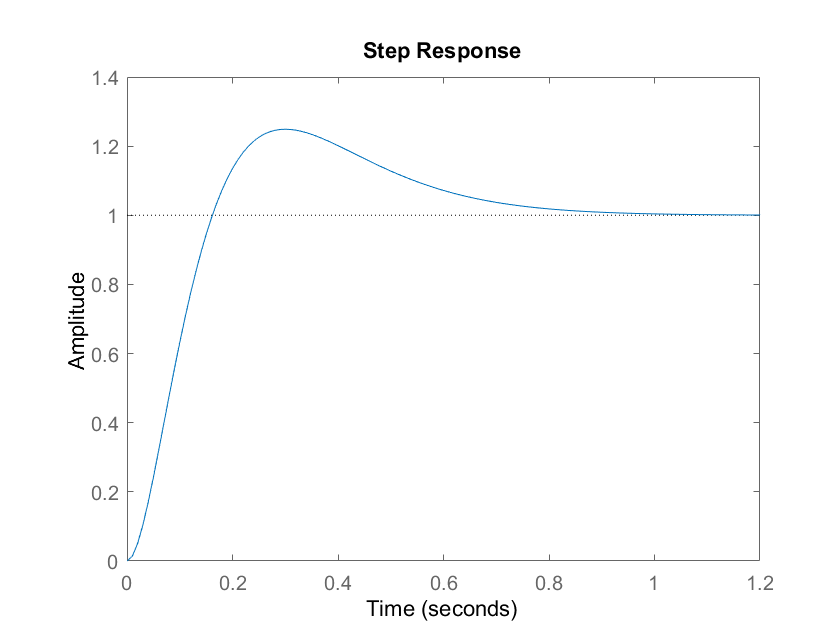

figure;
step(Ts_4c);

%% Problem 5 %%
s = tf('s');
K_5 = 10;
beta_5 = (1+sind(16))/(1-sind(16));
Gs_5 = tf([5],[0.05 1 0]);
w1a_5=sqrt(1000/sqrt(beta_5)); %% tau = .05
w1b_5=sqrt(1250/sqrt(beta_5)); %% tau = .04;
w1c_5=sqrt(833.33333/sqrt(beta_5)); %% tau = .06;
Ha_5 = (1+s/w1a_5)/(1+s/(w1a_5*beta_5));
Hb_5 = (1+s/w1b_5)/(1+s/(w1b_5*beta_5));
Hc_5 = (1+s/w1c_5)/(1+s/(w1c_5*beta_5));
LGa_5 = K_5*Gs_5*Ha_5;
LGb_5 = K_5*Gs_5*Hb_5;
LGc_5 = K_5*Gs_5*Hc_5;
Tsa_5 = feedback(LGa_5, 1);
Tsb_5 = feedback(LGb_5, 1);
Tsc_5 = feedback(LGc_5, 1);
del_max_5 = 46.9*(pi/180)/33.3;
Gs_5_del = tf([5], [0.05 1 0], 'IODelay', del_max_5);
LG_5_del = K_5*Ha_5*Gs_5_del;
Ts_5_del = feedback(LG_5_del, 1);
u_5 = sin(2*t);
resp_5 = lsim(Tsa_5, u_5, t);
lambda_5e = .05;
beta_5e = 3*lambda_5e;
fs_5e = (1+beta_5e*s)/(1+lambda_5e*s)^3;
Ts_5e = fs_5e;
Qs_5e = Ts_5e/Gs_5;
Hs_5e = Qs_5e/(1-Ts_5e);
Ts_5e_comp = feedback(Hs_5e*Gs_5, 1);
resp_5e = lsim(Ts_5e, u_5, t);

I am satisfied with the sensitivity to changes in time constant.

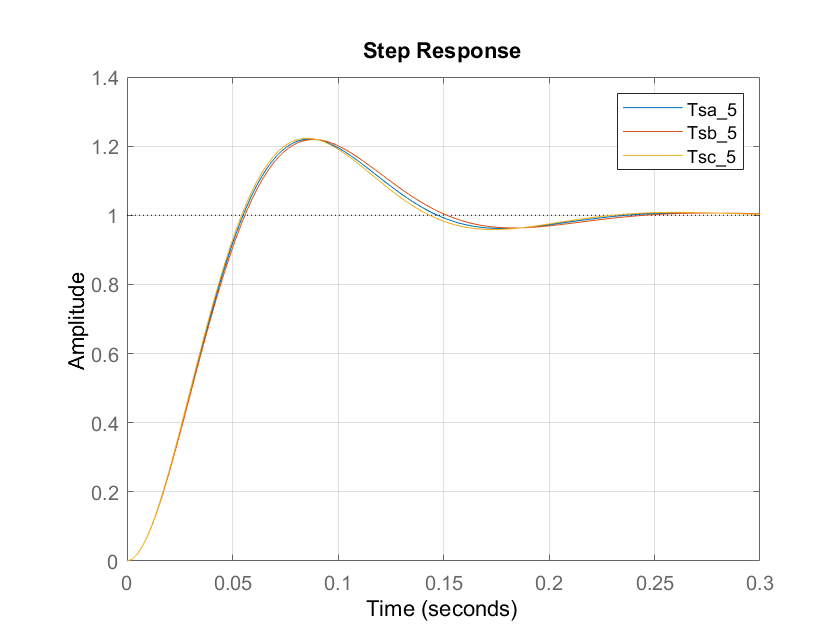

figure;
step(Tsa_5), grid;
hold on;
step(Tsb_5), grid;
step(Tsc_5), grid;
legend;
hold off;

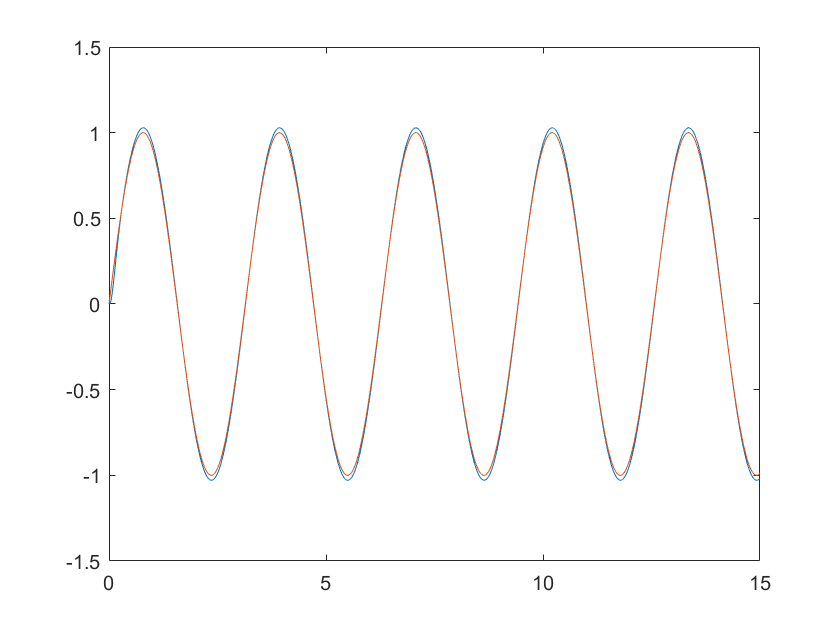

figure;
plot(t, resp_5e);
hold on;
plot(t, u_5);
hold off;

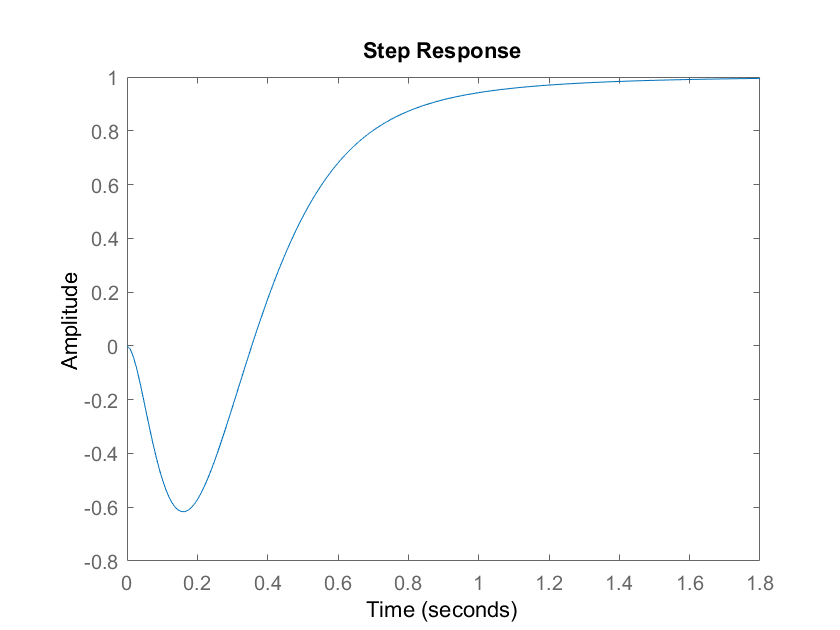

%% Problem 6 %%
s = tf('s');
Gs_6 = tf([-1.117 3.1472], [1 4.6429 5.3821]);
lambda_6 = .1;
beta_6 = .3;
Gsa_6 = tf([-1.117 3.1472],[1.117 3.1472]);
fs_6 = (1+beta_6*s)/(1+lambda_6*s)^3;
Ts_6 = fs_6*Gsa_6;
Qs_6 = Ts_6/Gs_6;
Hs_6 = Qs_6/(1-Ts_6);
Ts_6_comp = feedback(Hs_6*Gs_6, 1);
step(Ts_6_comp);

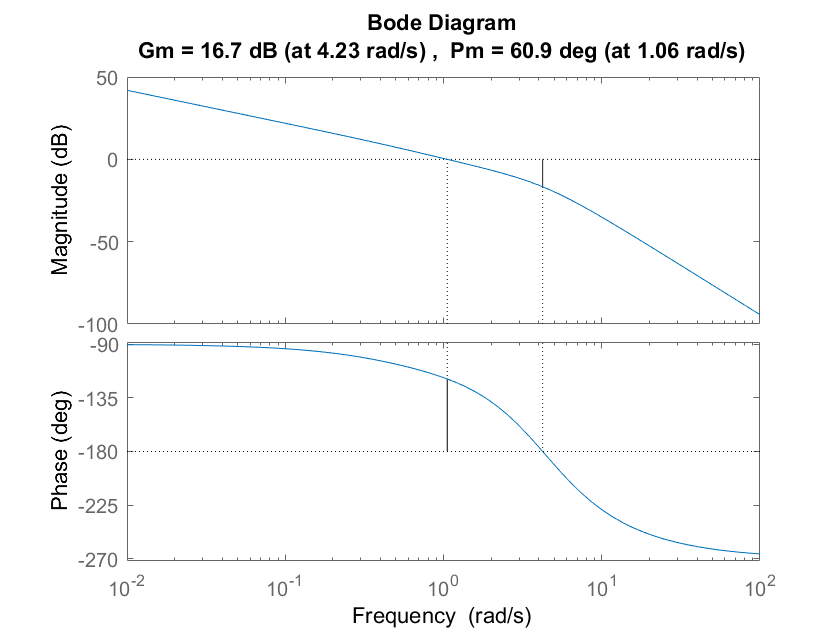

%% Problem 7 %%
s = tf('s');
Gs_7 = 1/s;
lambda_7 = .5;
beta_7 = 4*.3;
fs_7 = (1+beta_7*s)/(1+lambda_7*s)^4;
Ts_7 = fs_7;
Qs_7 = Ts_7/Gs_7;
Hs_7 = Qs_7/(1-Ts_7);
LG_7 = Hs_7*Gs_7; 
Ts_7_comp = feedback(LG_7, 1);
margin(LG_7);